1. 蒙哥马利量表（MADRS）是一种常用于评估严重抑郁症状的工具。该量表包含10个项目，每个问题的得分范围是0~6分。一般来说，MADRS总分的解释如下： 7~19分：轻度抑郁症状；20~34分：中度抑郁症状；35~60分：重度抑郁症状。在一项实验中，研究人员记录了每个被试的量表评分，并将这些数据保存在一个名为“01_MADRS.mat”的MATLAB文件中。请编写一个MATLAB程序，计算每个被试的总分数，并报告所有重度抑郁被试在数据库中的编号。最后，使用合适的图表将所有被试MADRS总分的分布绘制出来。

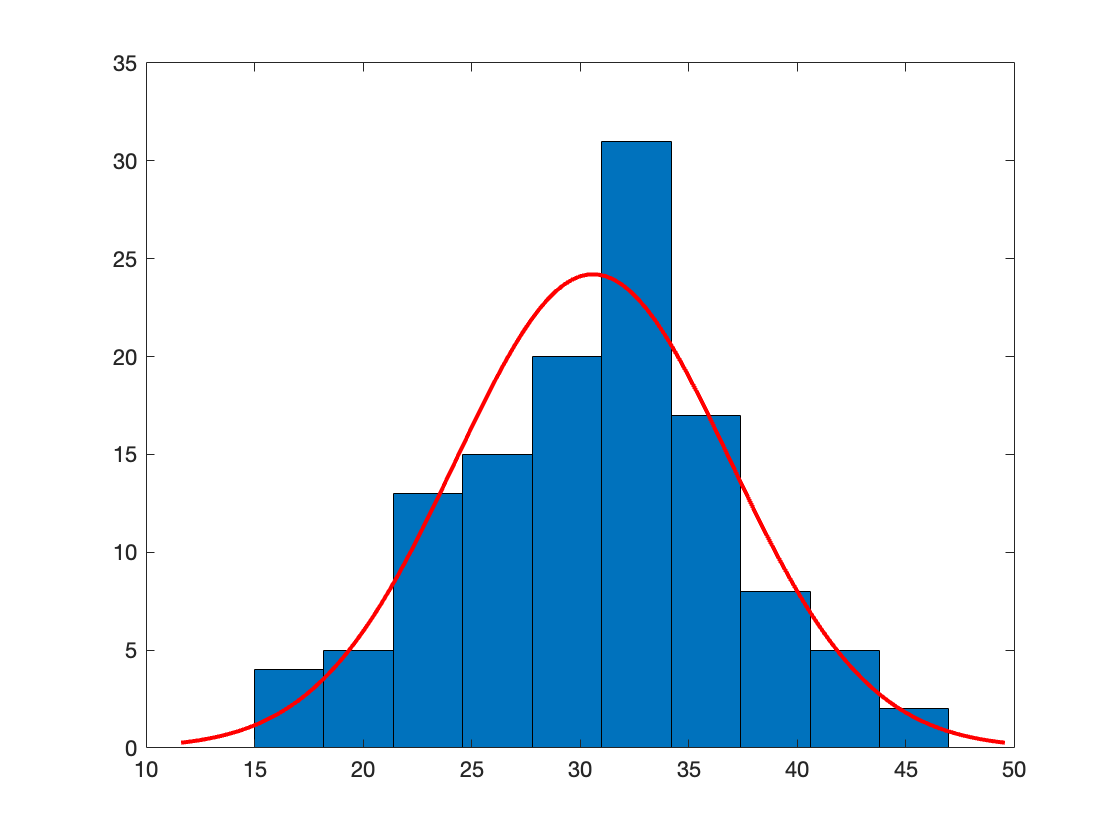

load 01_MADRS.mat
scores = sum(MADRS,2);
index = find(scores>=35 & scores<=60);

histfit(scores,10)

2. 在一项有30名被试参与的热痛实验里，研究人员要求被试在每个试次里用最短的时间判断接受到的刺激为低痛或高痛。每个被试都完成了20个试次，每个试次有4个变量：时间（秒）、判断时间（毫秒）、刺激类型（1代表低痛，2代表高痛）和正确性（1代表正确，0代表错误），数据保存在名为“02_data_heat.mat”的文件中。要求编写一个MATLAB脚本来计算每个被试在低痛和高痛下的平均判断时间和正确率，并将结果存储在一个名为“results”的结构体中。结构体应该具有以下内容：a) 'subjectID': 包含所有被试ID，以subj打头；b) 'meanRT_A': 包含每个被试在低痛下的平均反应时间；c) 'meanRT_B': 包含每个被试在高痛下的平均反应时间；d) 'accuracy_A': 包含每个被试在低痛下的正确率；e) 'accuracy_B': 包含每个被试在高痛下的正确率

load 02_data_heat.mat

% results.subjectID = '';
% results.meanRT_A = ;
% results.meanRT_B = ;
% results.accuracy_A = ;
% results.accuracy_B = ;

[r,c] = size(data_heat);
for row=1:r
    res(row).subjectID = ['subj' num2str(data_heat(row).subjectID)];
    low = find(data_heat(row).stimulusType == 1);
    high = find(data_heat(row).stimulusType == 2);
    res(row).accuracy_A = mean(data_heat(row).accuracy(low));
    res(row).accuracy_B = mean(data_heat(row).accuracy(high));
    
    res(row).meanRT_A = mean(data_heat(row).reactionTime(low));
    res(row).meanRT_B = mean(data_heat(row).reactionTime(high));
    
end

save('results.mat', 'res');

3. 在某次功能磁共振成像实验中，被试做手指点击任务，我们观察运动皮层的BOLD信号激活。但主试小W同学记录错了任务开始的时间。我们提取运动皮层的脑信号(BOLD蓝色实线)，参照错误的任务设计(X红色实线)，需要找到正确的实验设计时间（黑色虚线），如图示。请读取文件03_MotorTask.mat，编程找出需要将X移动几秒才对？（提示：移动X数据n步，得到与BOLD数据拟合最佳）

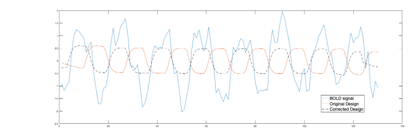

load 03_MotorTask.mat


[correlation, lag] = xcorr(X, BOLD);
[~, max_index] = max(correlation);
best_shift = lag(max_index)

best_shift = 7

4. 经皮神经电刺激(TENS)是一种常见的物理镇痛方式，通过对皮肤表面施加方波 电流起到镇痛作用。现开展了一项研究，在所有被试右手施加 TENS 干预，分别 在干预前后对左右双手施加测试性热痛刺激，并要求被试对疼痛不愉悦度进行 评分。 

提示:任务为 2*2 被试内设计，因变量为被试对疼痛刺激诱发不愉悦度的主观评分。

自变量 1:刺激位置(left VS right)

自变量 2:刺激顺序(pre VS post) 

04_class_test.xlsx 文件中是 30 名被试的疼痛不愉悦度评分数据。 ID:被试编号

left_pre:

左手前测评分

left_post:

左手后测评分 

right_pre:右手前测评分 right_post:右手后测评分 

要求:

1. 

请读取文件并定义每列变量

2. 

请计算四个条件下的平均分和标准差

3. 

请绘制四个条件下的分布直方图，添加高斯分布拟合曲线

4. 

请判断:TENS 镇痛效果在测试位置和测试顺序之间是否存在显著交互作用? (重复测量方差分析) 

% 读数据并定义变量
tens = xlsread("04_class_test.xlsx");
ids = tens(:,1);
left_pre = tens(:,2);
left_post = tens(:,3);
right_pre = tens(:, 4);
right_post = tens(:, 5);


% 计算平均分和标准差
left_pre_mean = mean(left_pre);
left_post_mean = mean(left_post);
right_pre_mean = mean(right_pre);
right_post_mean = mean(right_post);

left_pre_std = std(left_pre);
left_post_std = std(left_post);
right_pre_std = std(right_pre);
right_post_std = std(right_post);

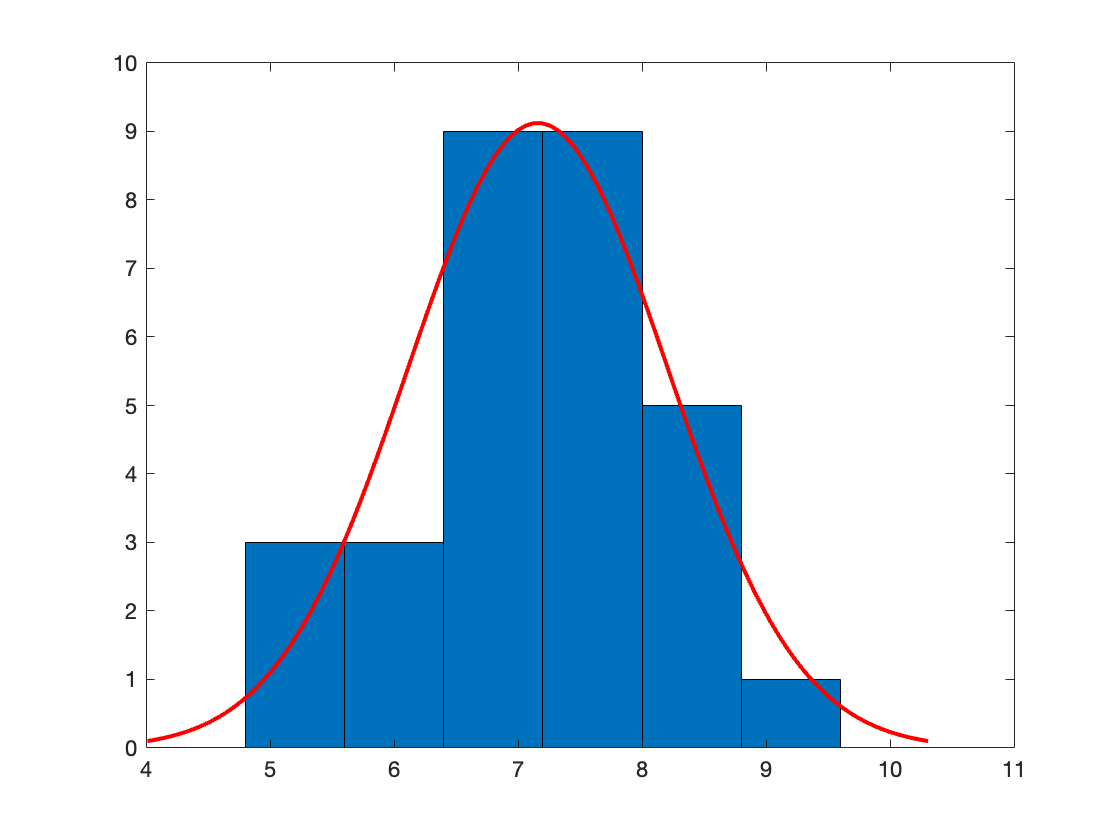


% 绘制直方图，添加高斯分布拟合曲线
histfit(left_pre);

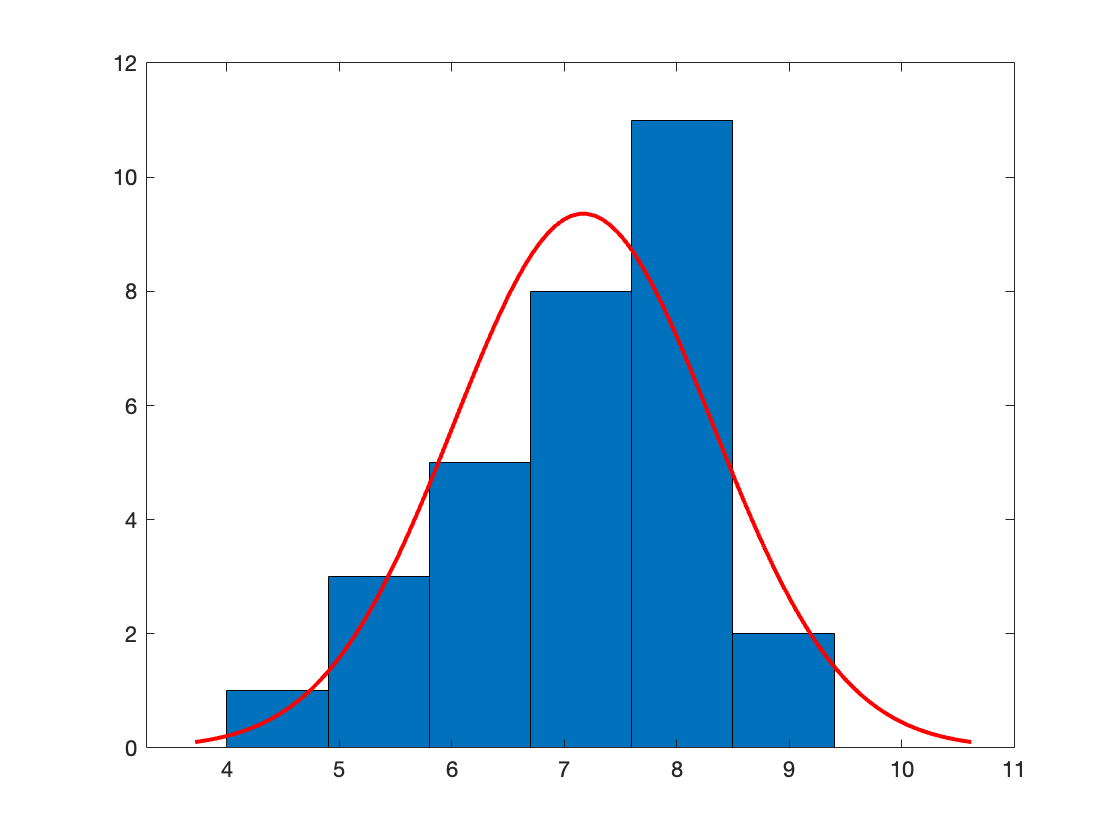

histfit(left_post);

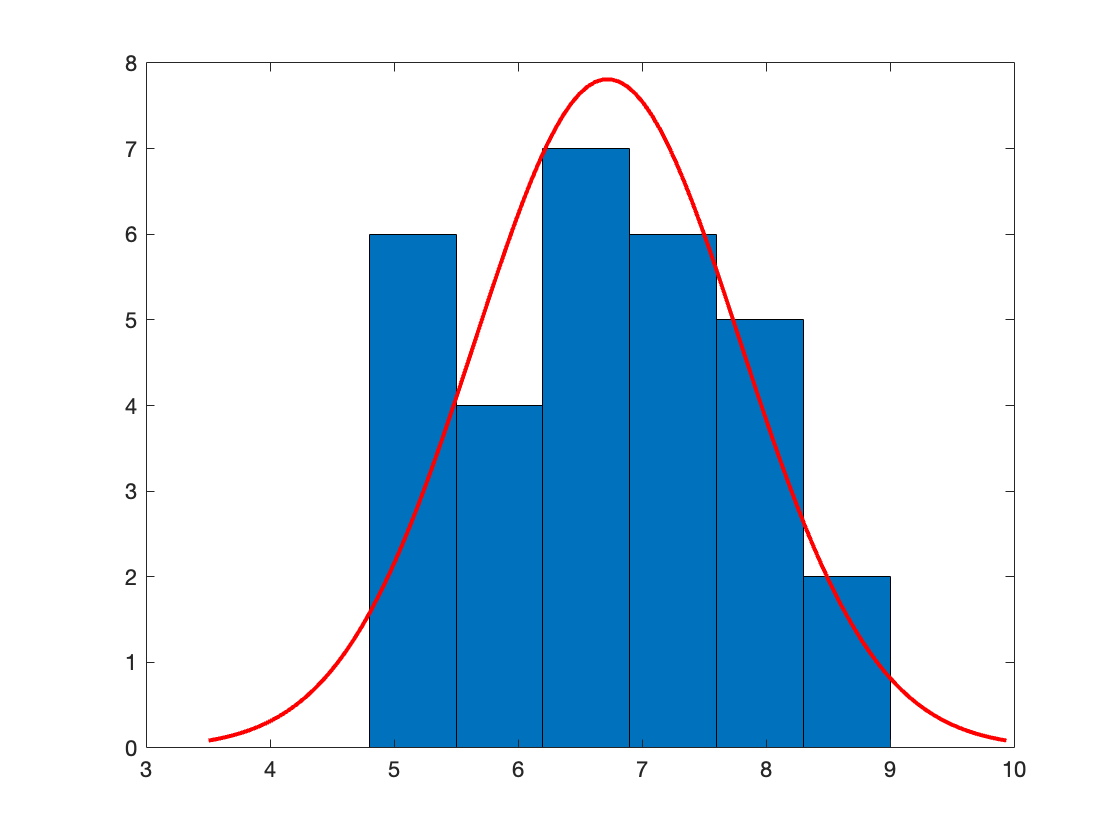

histfit(right_pre);

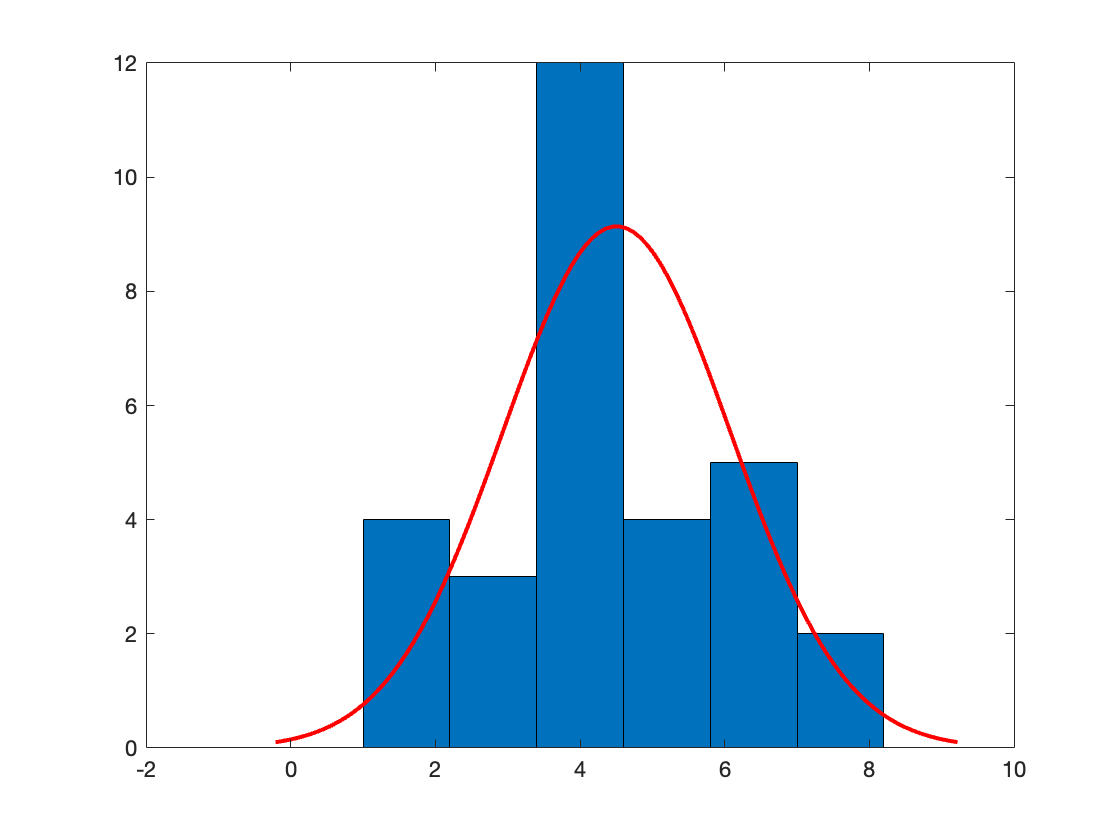

histfit(right_post);

% 判断是否存在显著交互作用
% 测试样例的结构：6.60000000000000	7	4.93000000000000	4.53000000000000
%       left    right
% pre   6.6     7
% post  4.93    4.53

[r c] = size(tens);
for i=1:r
    
end
[p c s] = anova2(X, 2);